# Lab 8

### Jessie Li // November 15, 2023

### 1A. Solving the bioheat equation with Crout LU decomposition

ans = 0.0048

ans = 0.0012

ans = 3.0349e-04

ans = 7.5931e-05

ans = 1.8998e-05

ans = 4.7496e-06

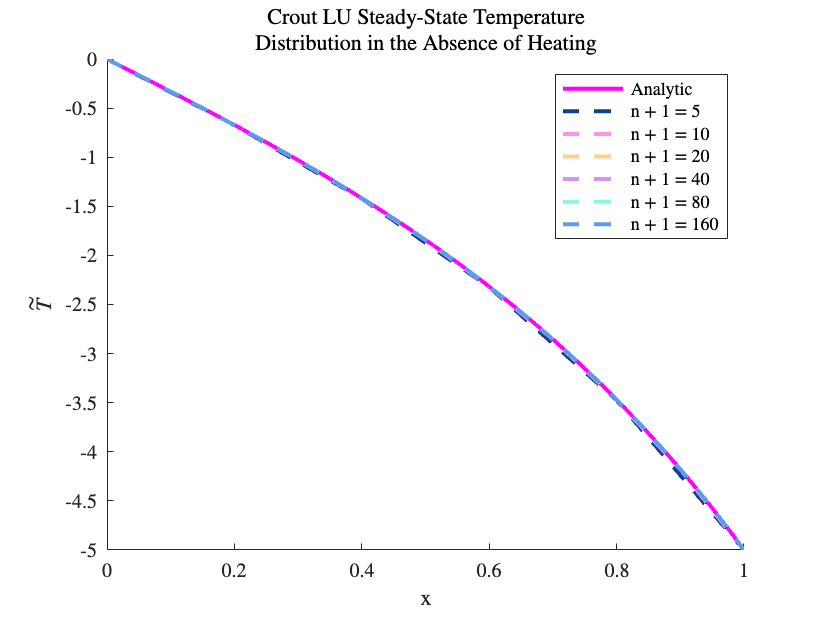

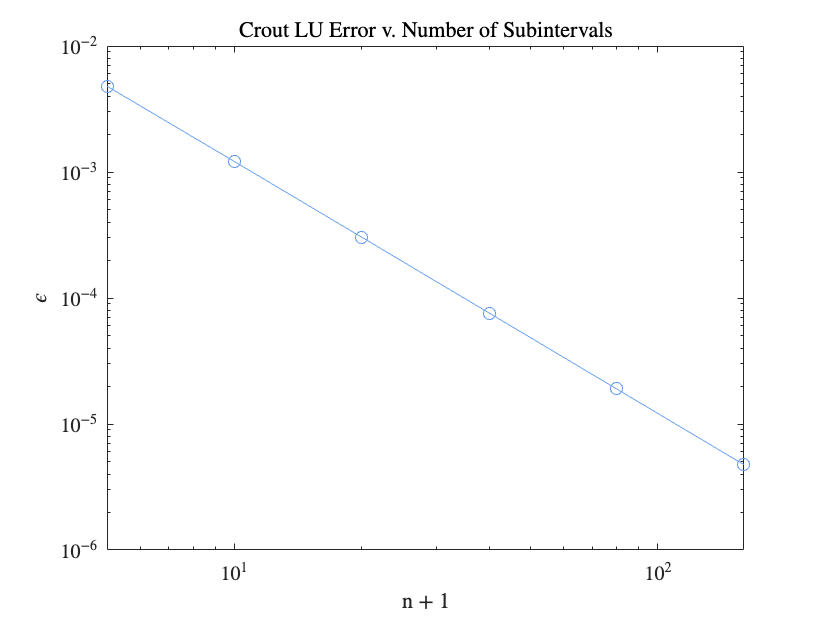

errLU =     0.0048    0.0012    0.0003    0.0001    0.0000    0.0000


errLU = main1a()

### 1B. Solving the bioheat equation with Gauss-Seidel iteration 

n + 1 = 5: Gauss-Seidel converged after 11 iterations.
n + 1 = 10: Gauss-Seidel converged after 12 iterations.
n + 1 = 20: Gauss-Seidel converged after 50 iterations.
n + 1 = 40: Gauss-Seidel converged after 54 iterations.
n + 1 = 80: Gauss-Seidel converged after 137 iterations.
n + 1 = 160: Gauss-Seidel converged after 194 iterations.


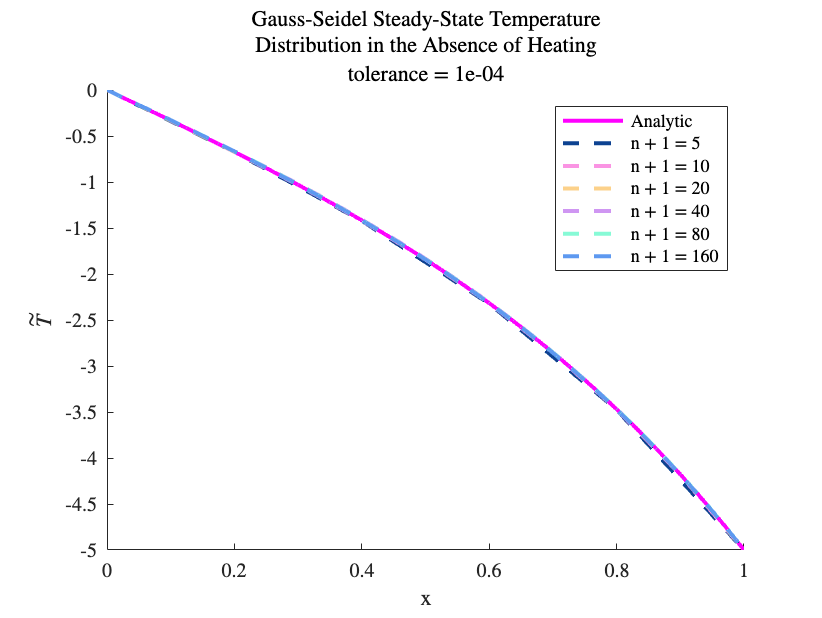

n + 1 = 5: Gauss-Seidel converged after 15 iterations.
n + 1 = 10: Gauss-Seidel converged after 31 iterations.
n + 1 = 20: Gauss-Seidel converged after 127 iterations.
n + 1 = 40: Gauss-Seidel converged after 288 iterations.
n + 1 = 80: Gauss-Seidel converged after 377 iterations.
n + 1 = 160: Gauss-Seidel converged after 515 iterations.


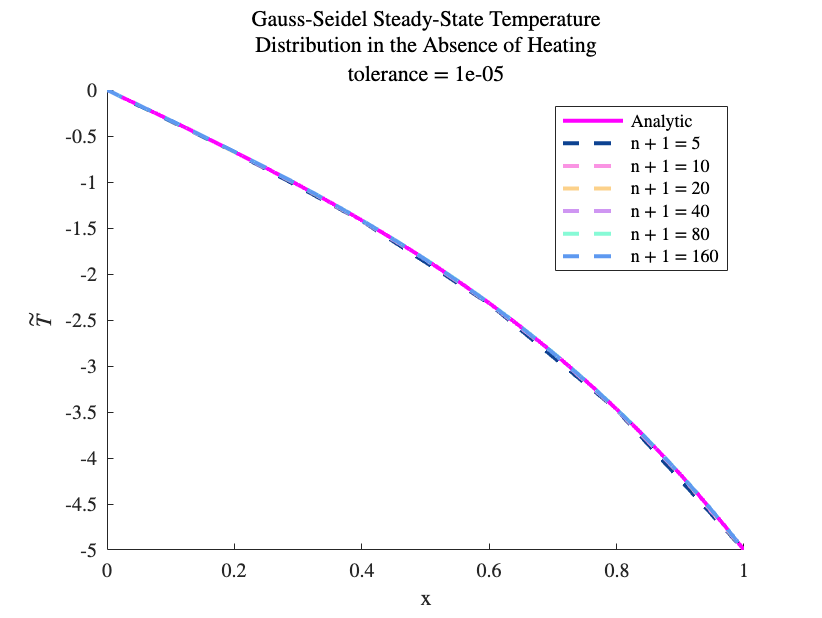

n + 1 = 5: Gauss-Seidel converged after 19 iterations.
n + 1 = 10: Gauss-Seidel converged after 49 iterations.
n + 1 = 20: Gauss-Seidel converged after 200 iterations.
n + 1 = 40: Gauss-Seidel converged after 576 iterations.
n + 1 = 80: Gauss-Seidel converged after 996 iterations.
n + 1 = 160: Gauss-Seidel converged after 1486 iterations.


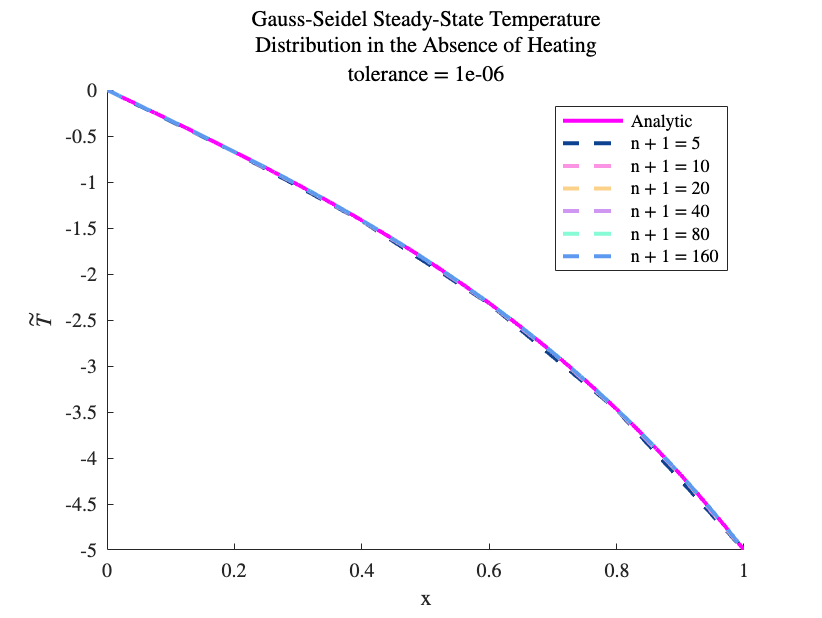

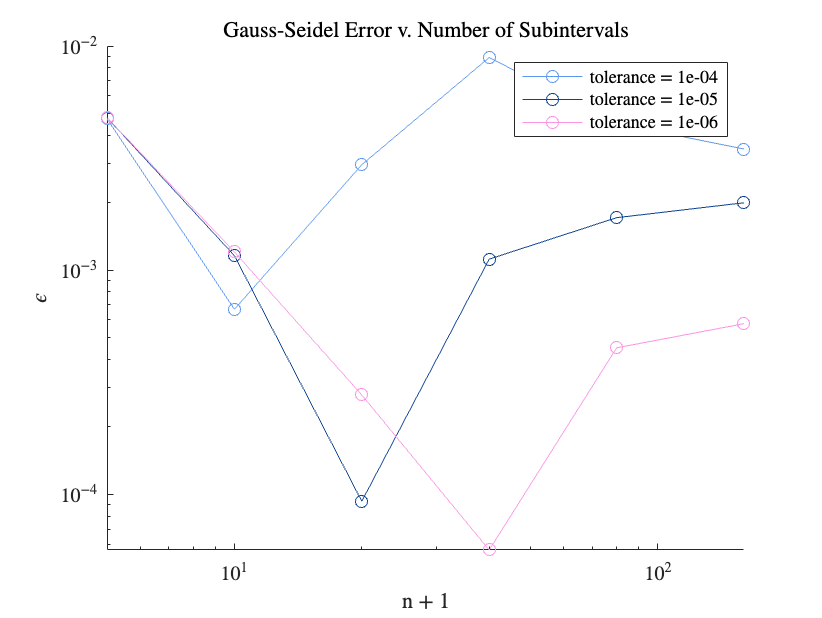

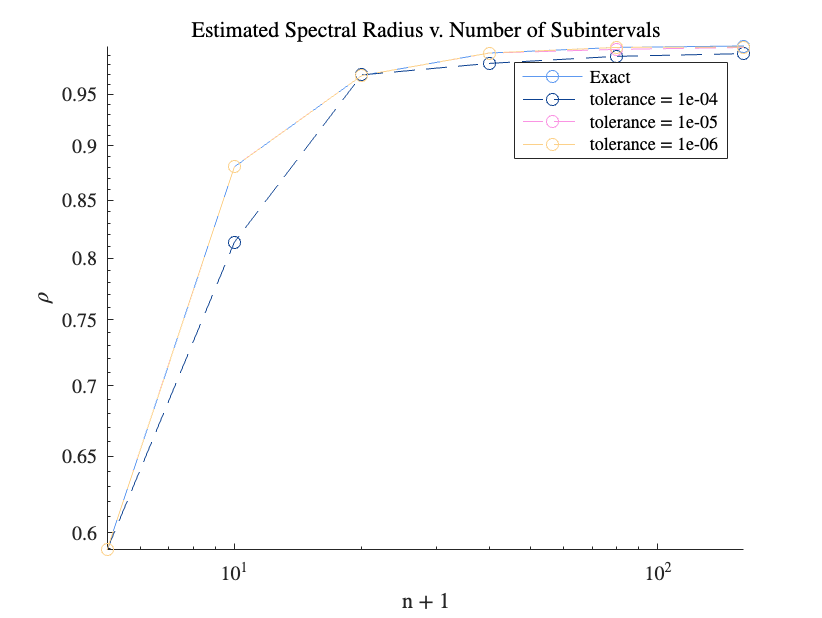

errGaussSeidel =     0.0047    0.0007    0.0030    0.0089    0.0045    0.0035
    0.0048    0.0012    0.0001    0.0011    0.0017    0.0020
    0.0048    0.0012    0.0003    0.0001    0.0005    0.0006


errGaussSeidel = main1b()

### 1C. Solving the bioheat equation over time with a Crank-Nicholson time-stepping algorithm  

reached steady-state after 27 iterations
reached steady-state after 54 iterations
reached steady-state after 110 iterations
reached steady-state after 215 iterations
reached steady-state after 417 iterations
reached steady-state after 803 iterations


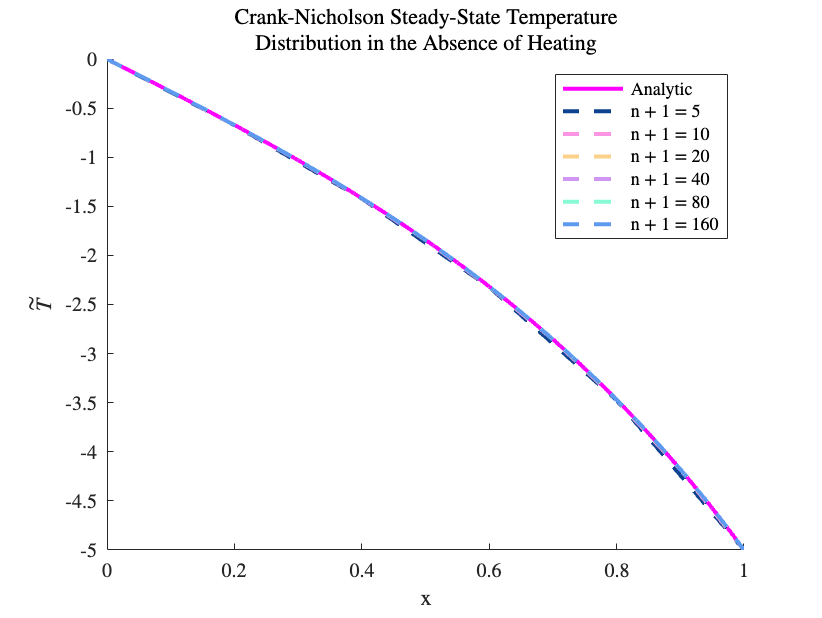

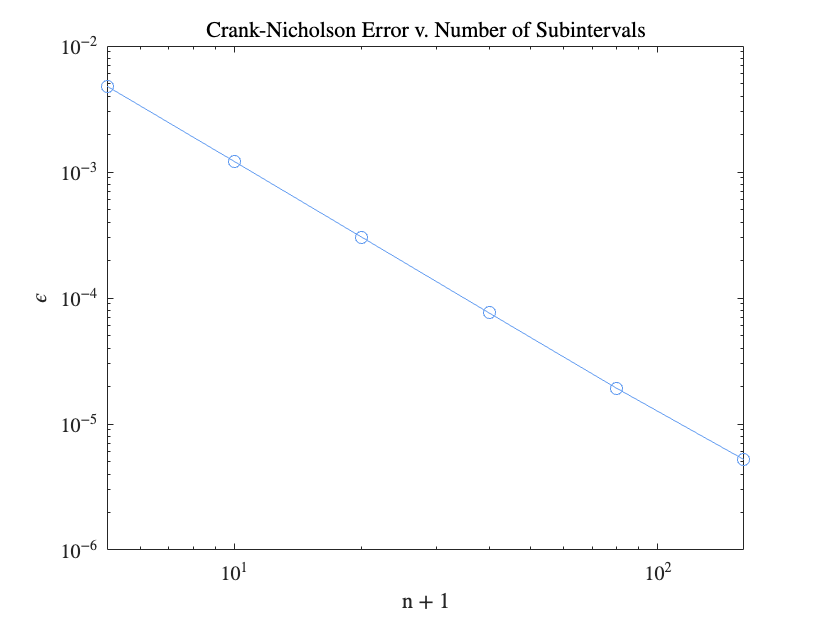

errCrankNicholson =     0.0048    0.0012    0.0003    0.0001    0.0000    0.0000


errCrankNicholson = main1c()

### Error summary

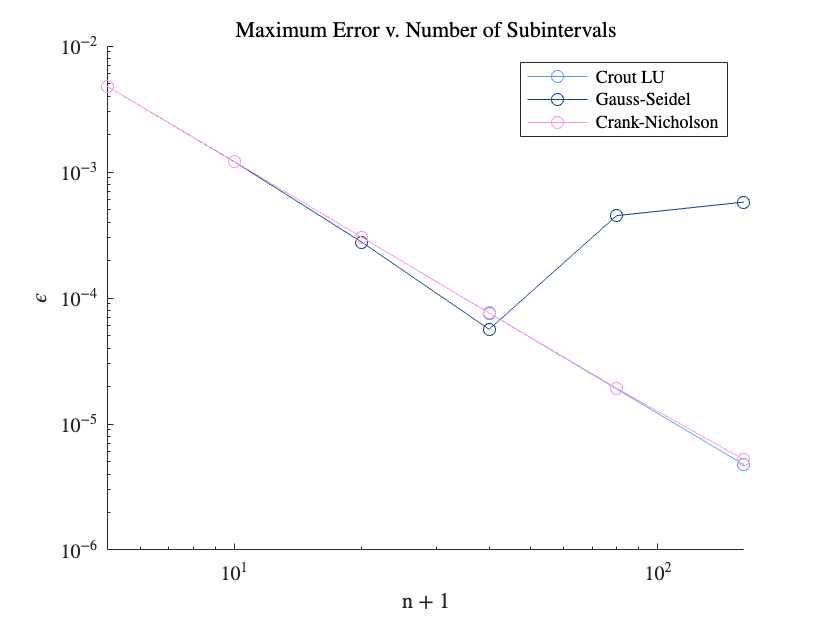

% plot errors on the same graph
set(groot, 'DefaultAxesTickLabelInterpreter', 'latex');
set(groot, 'DefaultTextInterpreter', 'latex');
set(groot, 'DefaultLegendInterpreter', 'latex');

nSubintervals = [5, 10, 20, 40, 80, 160];

figure
defaultColors()

hold on
% finite difference with Crout LU decomposition
plot(nSubintervals, errLU, '-o', 'DisplayName', 'Crout LU')

% finite difference with Gauss-Seidel, smallest tolerance
plot(nSubintervals, errGaussSeidel(end, :), '-o', 'DisplayName', 'Gauss-Seidel');

% Crank-Nicholson "steady-state" solution
plot(nSubintervals, errCrankNicholson, '-o', 'DisplayName', 'Crank-Nicholson')
hold off

set(gca, 'YScale', 'log', 'XScale', 'log');
ylabel('$\epsilon$')
xlabel('n + 1')
title({'Maximum Error v. Number of Subintervals'})
legend()


function defaultColors()
    color_order = [0.37 0.60 0.94
                   0.05 0.26 0.57
                   0.98 0.58 0.89
                   0.99 0.82 0.54
                   0.81 0.59 0.95
                   0.53 0.98 0.84];
    
    colororder(color_order)
end